# MEC326/7 Introduction to Modal Analysis: Matlab Tutorial

T. J. Rogers, P. A. Gardner, J. A. Rongong & E. J. Cross

## 1. Introduction

This tutorial will walk you through some basic signal processing in Matlab  and give an introduction to processing dynamic test data. This tutorial will help you through the code that will be the foundation for the "Modal Analysis in Matlab" assignment in MEC326/7. 

Please note that the previous tutorial, which covers the basic use of Matlab, is a prerequisite for this tutorial.

#### 1.1 Intended Learning Outcome

To be able to use Matlab to calculate and plot the Frequency Response Function(s) of a structure from experimental data.

#### 1.2 Content Covered

- Signals in the time and frequency domain

- Unwanted effects of signal processing

- The effect of nosie on a signal

- Repeated measurements and averaging

- Forming FRFs from data

To use this script you can write code in the boxes provided to complete the tasks, then run that section to see the output by either clicking "Run Section" in the toolbar or pressing <CTRL+ENTER>.

To get a better look at a figure you might want to move it to its own window by pressing the circle with an arrow coming out of it in the top right. If you are stuck ask a GTA.

By the end of this session make sure you have looked at the section "Forming FRFs of Experimental Data", this is the starting point for your assignment.

## 2. Signals in the Time and Frequency Domain

### 2.1 The Sine Wave

We will start with arguably the simplest (interesting) signal that we might encounter: the sine wave. Remember that if we have a linear dynamic system excited by a sine wave its response will be a sine wave at the same frequency (but maybe a different amplitude and phase). We can write an equation to define the sine wave as,


$$$$ x(t) = A \sin\left(\omega t + \phi\right) $$$$


For a signal $x(t)$ which is a sine wave with amplitude $A$, frequency $\omega$ and phase offset $\phi$, both in radians.

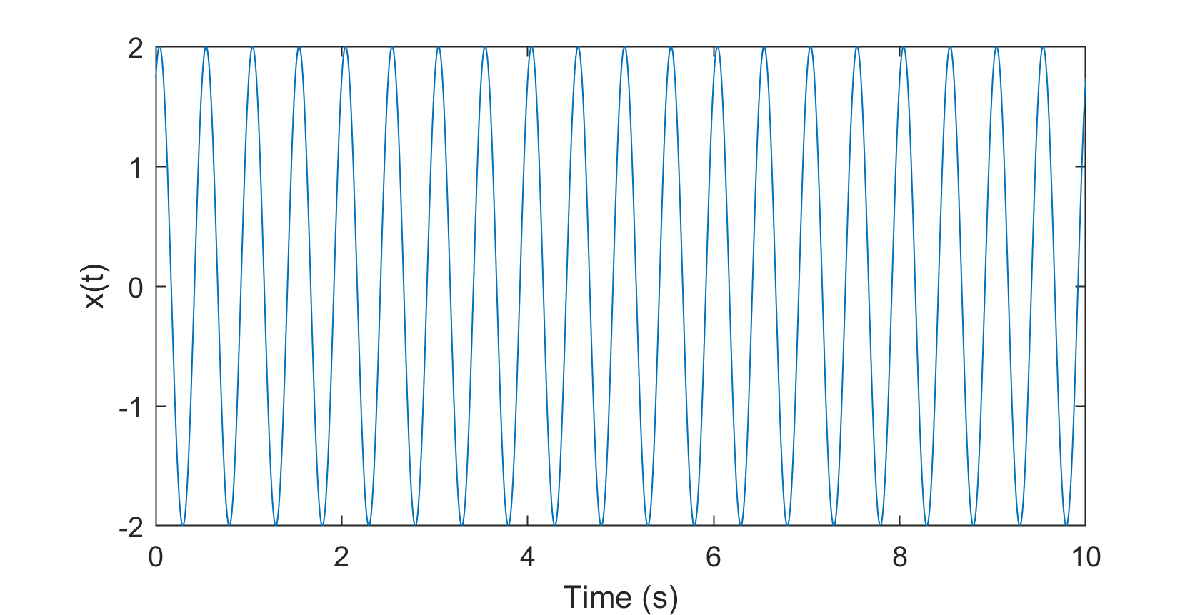

Although we understand that a sine wave is a continuous signal, i.e. we can measure it at any point in time, when working with physical data it is only possible to observe that data at discrete time intervals. 

Usually, we will choose a set of intervals that are (ideally) equally spaced. We call the time between these sample points the *sampling time (*$\Delta t = t_i - t_{i-1}$ for any point $i$) and define the rate at which we take samples as the *sampling frequency *($$f_s$$). If $$\Delta t$$ is in seconds then $$f_s$$ will be in Hertz and we can define,

 
$$$$ f_s = \frac{1}{\Delta t} $$$$


In Matlab, as in all computing, we are also limited to discrete representations of continuous signals. In other words, if we want to compute something like a sine wave we can only do so at a fixed set of $N$ points $\mathbf{t} = \left\{t_1,t_2,\ldots,t_N\right\}$.

Let's begin by simply creating and plotting a sine wave with a known frequency.

**Task: **In the box below write codes that defines and plots a signal $x(t)$ which is sine wave with an amplitude 2, a frequency of 5 Hz and no phase offset for a period of time from 0 to 5 seconds. Choose a sampling frequency that gives a smooth looking plot.

% Code to create the wave
T=5;
[t,waves] = make_test_waves();

Unrecognized function or variable 'make_test_waves'.

plot(t,waves)
% Make plot


### 2.2 Working out a solution

Let's look at this example, to construct the signal we will need to use the formula for a sine wave we saw before. In this case $A = 2$, $f = 5 Hz$ which is $\omega = 2\pi \cdot 5$ radians and $\phi = 0$ (so we can ignore it). To make the sine wave we will need evaluate the formula at a set of values for $t$, for this we will need to make a vector in Matlab containing those values. This vector will run from 0 to $T=5$ in steps of $\Delta t = 1/f_s$. One thing we often do in programming tasks is write out *pseudocode *which gives a summary of the steps needed to complete a task. This makes it easier to search for help online or to ask specific questions. Let's do this for the sine wave example.

- `Define constants fs (sample freq.), A and f`

- `Construct time vector (t = 0:1/fs:T).`

- `Compute x using A*sin(2*pi*f*t)`

- `Create and label plot (x against t)`

This gives us the structure of our code which may seem obvious here but can be very useful when dealing with more complicated problems later. The golden rule when approaching programming tasks is to break big problems down into the smallest logical parts.

Your figure should look like this: 

**ADD IMAGE**

### **2.3 More Complex Waveforms**

As we said the sine wave is really the most simple wave we would ever look at, most signals encountered when analysing physical test data will be significantly more complex. They may contain multiple different types of signals and/or noise. We will now create some more complex waveforms using the function `make_test_waves()`. Run the code below to clear your workspace and to call this function (the function will need to be available in your current folder).

% clear % Clear workspace (remove all data)
% [t,waves] = make_test_waves(); % Call function

Running this function has stored the example waves in a matrix `waves` where each column is one signal at the corresponding time `t`. There are  5 columns so 5 different signals.

**Task: **In the code box below write code which will create a single figure with each wave plotted in its own subplot (*Hint: you will need to use *`subplot`*, see the previous tutorial*). Each plot should be the signal plotted against time, make sure to add axes labels. For each plot, by eye, estimate how many different frequency components there are and if there is any noise present.

% % Code to plot the waves in subplots
% for i=1:5
% subplot(5,1,i), plot(t,waves(:,i))
% end



The plot should look like the one below.

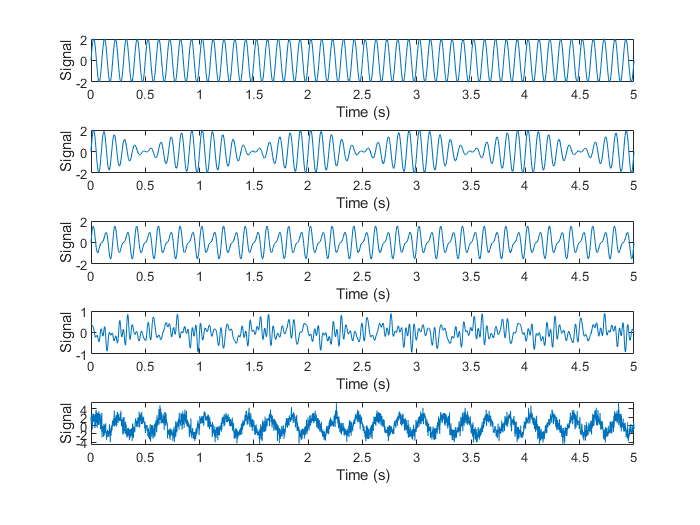

### 2.4 The Fourier Transform

You hopefully remember from previous mathematics courses that we can represent a periodic function as a weighted sum of sine and cosine waves, this is called a [Fourier Series](https://en.wikipedia.org/wiki/Fourier_series). Another way to write the Fourier series is as a sum only over sine or cosine waves but with a phase offset. The final representation of the Fourier series is to apply [Euler's Identity](https://en.wikipedia.org/wiki/Euler%27s_identity) to write the signal as a weighted sum over complex exponentials:


$$y(x) = \sum_{n=-N}^N c_n\; e^{\mathbf{\mathrm{i}}\;\frac{2\pi}{P}\;nx}$$


where $c_n$ is the coefficient and $P$ is the length of the periodic interval, for an $N$term Fourier series.

We can consider a generalisation of this approach which would allow any signal in time $y(t)$to be modelled as a function of frequency $Y(\omega)$ instead of time. The mathematical tool that achieves this is the [Fourier Transform](https://en.wikipedia.org/wiki/Fourier_transform). Before looking at the maths let's see what it can do. In the image below two subplots are shown. In the upper plot, we can see one of the waves from before in the *time domain*, i.e. there is time on the horizontal axis and amplitude on the vertical axis $y(t)$. The lower plot shows the amplitude in the *frequency domain* this has frequency on horizontal axis and the magnitude $\vert Y(\omega)\vert$ on the vertical axis.

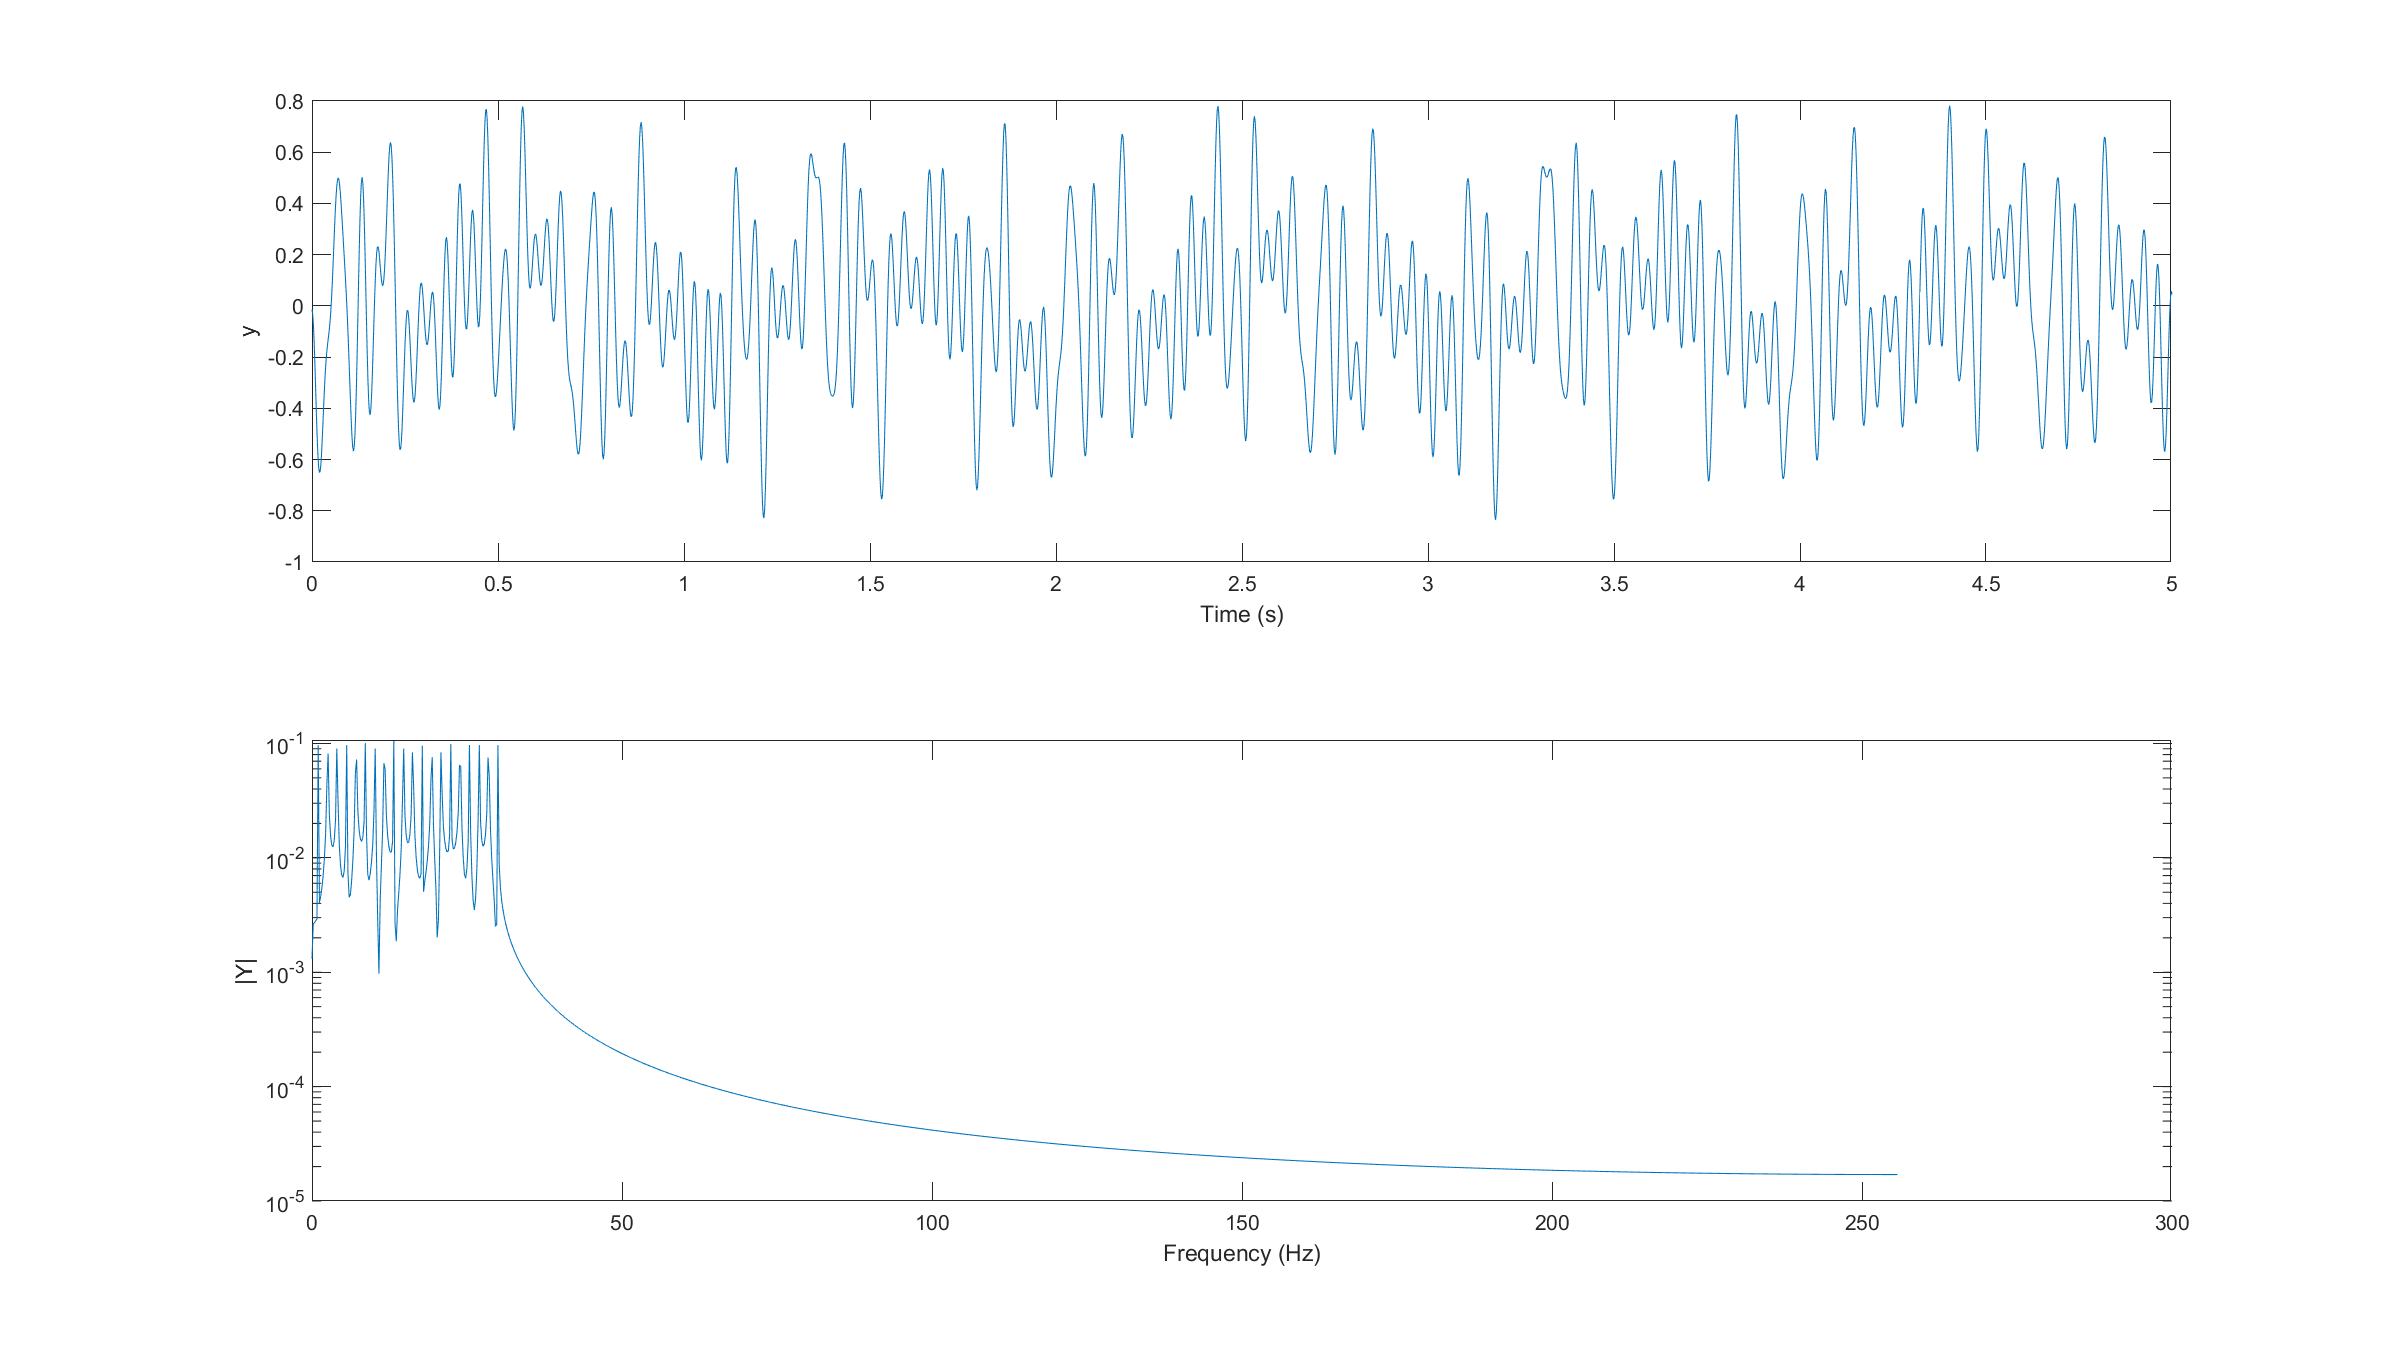

The useful thing about looking in the frequency domain view is that it is now clear that the top signal is only made up of two different frequency components which is harder to see at a glance from the upper plot in the time domain. Another very helpful feature of the Fourier Transform is that it preserves the information in the signal. In other words, the information in the frequency domain is exactly the same as in the time domain just presented differently. We also have access to the Inverse Fourier Transform which performs the opposite operation, moving data from the frequency domain to the time domain. Maybe obviously if we do the Inverse Fourier Transform on the Fourier Transform of $y(t)$ we end up back with $y(t)$. 

Now let's look at the maths. Below is the equation which gives the Fourier Transform of $y(t)$, 


$$Y(\omega) = \mathcal{F}\left[y(t)\right] = \int_{-\infty}^\infty\, y(t)\, e^{-\mathbf{\mathrm{i}}\; 2\pi\,f\,t}\mathrm{d}t$$


The Fourier Transform and its inverse are very closely related to the [Laplace Transform](https://en.wikipedia.org/wiki/Laplace_transform) which you may have seen previously.

The expression above tells us about the *continuous *Fourier Transform, i.e. the transformation on a continuous function $y(t)$, however, we have already said that in Matlab or with experiemental data we are normally working with discrete data series. We will use $y_n$ to represent the value of $y(t)$ at time $n\cdot \Delta t$ so for a sequence $n=1,\ldots,N$ we have the discretely sampled signal. Because the signal we are applying the Fourier Transform to is now discrete we use a different form called the *Discrete Fourier Transform *(DFT) to compute $Y_k$ for $k=0,\ldots,N-1$ the discrete version of $Y(\omega)$. This is shown below, notice that the integral becomes a sum over the discrete points,


$$Y_k = \sum_{n=0}^{N-1} y_n\,e^{-\mathbf{\mathrm{i}}\,2\pi\,nk/N$$
 

where,

- $N$- the number of data points in $y$

- $Y_k$ -  a complex number which represents the $k^\text{th}$ frequency component of the signal

- $y_n$ - the $n^\text{th}$ sample of the time domain data 

As you might be able to imagine, computing the DFT from the formula above has some difficulties, namely that it is $O(N^2)$ in computational complexity, i.e. it is a real pain. However, thanks to [Cooley and Tukey (1965)](https://doi.org/10.1090%2FS0025-5718-1965-0178586-1) we have access to the *Fast Fourier Transform *(FFT) a much more efficient algorithm which makes data analysis in the frequency domain feasible with a complexity of $O(N\log N)$. As a side note, the FFT is often cited as one of the most important discoveries of the 20th Century. The implementation of the FFT requires a certain amount of book-keeping to get optimal performace, thankfully, we do not need to worry about this as the algorithm is already coded in an efficient manner which is available in Matlab through the command `fft`. Remember you can bring up the documentation by typing` doc fft `in the console.

If we have a vector of values for a function stored in` x `then the following code will give the FFT of that time domain data and put it in the vector` X`.

We divide the FFT of the data by its length to preserve the power in the signal, this is one form of *normalisation* applied when performing the FFT which leaves the magnitude of` X `in an interpretable form.

**Task: **To put this to use we will take look at the Fourier Transform of a known wave. In the box below code is provided to construct a wave with one frequency, where indicated write code to take the FFT of that signal. Run this section and look at the plot produced.

% Create sine wave with frequency of 64 Hz and amplitude of 5, for 5 seconds
fs = 512; % Sample Rate
t = (0:1/fs:(5-1/fs))'; % Time Vector
y = 5 * sin( 2*pi*64*t ); % Create signal

% Your code goes here, complete below.
Y = fft(y)./length(y);



plot(real(Y), imag(Y))

Does this plot make sense to you?

Remember that `Y` will be a complex number (it has real and imaginary parts). If you try to plot complex numbers in Matlab it will produce a plot with the real part on the horizontal axis and the imaginary part on the vertical axis, i.e. it assumes you meant 

This is not normally what we are after in dynamics, usually we will consider the complex values in the Fourier Transform in terms of their magnitude and phase. In the previous tutorial we looked at how to convert complex numbers to their magnitude and phase. 

**Task: **In the box below try now plotting only the magnitude of the complex vector `Y (`*Hint: *`doc abs)`

% Plot magnitude of Y

plot(abs(Y))

You should see something that looks like this.

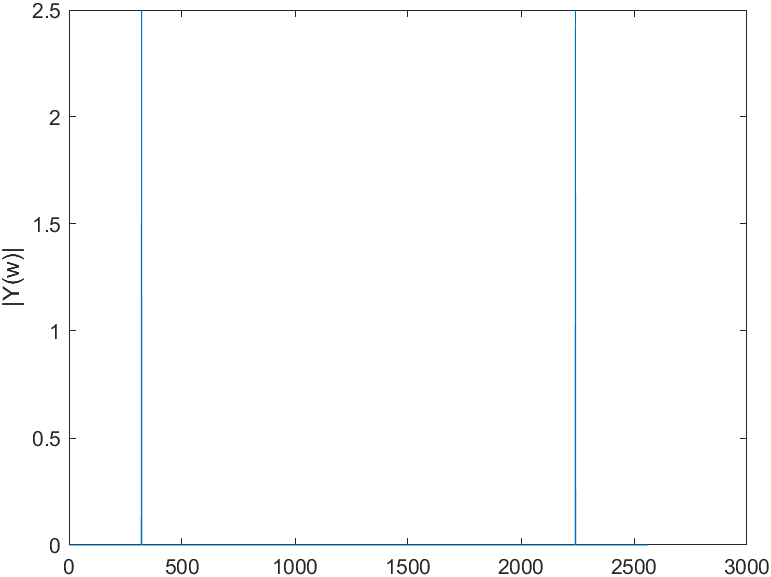

### 2.5 The Double and Single Sided-Spectrum

This still doesn't look like we would expect, with only a single sine wave in our signal we would think only one line would show up in the magnitude plot of the FFT... What you have here is the *Double-Sided Spectrum *the second half of the plot is a mirror image of the first half. There are some technical details which explains why this happens but we won't cover these here. Instead, let's focus on how to get the usable result we want. To get the single-sided spectrum we will "fold" the second half of the signal back onto the first half, because they are identical this is the same as doubling all the points in the first half of `Y` except the very first point (which corresponds to the 0 Hz line/DC-offset). This can be done as follows, assuming that `Y` is a column vector.

From now on we will assume that whenever taking the FFT we always convert to the single-sided spectrum unless specified.

**Task: **In the box below form the single sided spectrum of `Y` and plot its magnitude as before.

% Make the single sided spectrum

 Y = [ Y(1) ; 2*Y(2:end/2) ];

% Plot the magnitude 
plot(abs(Y))


Remember that in the frequency domain we have frequency on the horizontal axis. To determine the frequency content in the signal we should be able to look at where the lines are located along the horizontal axis. We also know that the amplitude of the sine waves that make up the signal will be equal to the magnitude of $Y(\omega)$, we can work out the amplitudes by reading the values off of the vertical axis.

**Task: **Look at the figure above. By looking at the location of the peak along the horizontal axis determine the frequency of the wave. Does this match the frequency of the wave we have created (64 Hz)? Does the amplitude given by the peak match the known amplitude of the wave (5)?

### 2.6 Computing the Frequency Vector

Hopefully you can see that the line in the figure above is not at 64 Hz as we would expect but instead is at value 257 on the horizontal axis. This is because we have not properly worked out what the corresponding frequencies are to the outputs of the FFT. For example, if I plot a sine wave but do not use the time on the x-axis and only use the sample number, there is no way to work out what frequency the wave is. It is the same in the frequency domain we must always plot the FFT against the corresponding *frequency vector*. The question remains, how do we work out what the correct frequencies are? 

To understand what the frequencies are we will go back to our definintion of the Discrete Fourier Transform (remember the FFT is just a clever way of computing this). The DFT is computed for $k=0,1,\ldotp \ldotp \ldotp ,N-1$using the formula shown below


$$Y_k = \sum_{n=0}^{N-1} y_n\,e^{-\mathbf{\mathrm{i}}\,2\pi\,nk/N$$
 

where,

- $N$- the number of data points in $y$

- $Y_k$ -  a complex number which represents the $k^\text{th}$ frequency component of the signal

- $y_n$ - the $n^\text{th}$ sample of the time domain data 

The term $e^{-\mathrm{i}2\pi\, nk/N$defines a complex trogonometric function via [Euler's Formula](https://en.wikipedia.org/wiki/Euler%27s_formula) equal to $\cos\left( 2\pi\, nk/N \right) - \mathrm{i} \sin\left( 2\pi\, nk/N \right)$. From this is is hopefully obvious that the frequency associated with $Y_k$ will be $nk/N$ Hz. Because our maximum frequency will be the sample frequency of the data, when $k = N$ the frequency $\omega_k = f_s$ (the sample frequency). Therefore, we can write that the vector of frequencies, $\{\omega\}$, which contains $\omega_k,\quad k = 0,1,\ldots,N-1$ can be build by finding,


$$\omega_k = k \frac{f_s}{N}$$


There is one more complication, remember that only the first half of our spectrum contains interesting information? This means we only actually need the first half of $\{\omega\}$. All frequencies higher than $f_s/2 $ will be discarded because of the Nyquist-Shannon Sampling Theorem. This means we can actually only calculate the frequencies for $k = 0,1,\ldots,(N-1)/2$, if $N$is odd we round down.

**Task: **Let's see this in action, using the formula above calculate a the correct frequency vector corresponding to the signal` y `that was created previously then plot the figure with` abs(y) `on the vertical axis and the frequencies` freqs `on the horizontal axis. Because the frequency lines are discrete, this time use `bar` instead of `plot` to create the figure. You might need to zoom in.

% Make Vector of Frequencies
% w = (0:fs/(2*length(Y)):((fs-1/fs)/2))';

k= (0:(length(Y)-1)/2)';
w=k*fs./(2*length(Y));
Y = [ Y(1,:) ; 2*Y(2:floor(end/2),:) ];
% w = [ w(1) ; 2*w(2:end/2) ];
% Plot Frequencies Against Magnitude (hint: doc bar)
bar (w,abs(Y))

Check the figure again and see if the line appears at the correct frequency (64 Hz).

**Task: **Using the box below, for each of the waves that are in the matrix `waves` we created earlier:

- Work out the sample frequency from the time vector

- Compute the FFT

- Compute the frequency vector

- Make a bar plot of the magnitude against the frequency in a set of subplots

- Work out how many different frequencies were in each wave and their relative magnitudes

Hint: Using a for loop will make this a lot quicker.

% Sample frequency from Data
clear % Clear workspace (remove all data)
[t,waves] = make_test_waves(); % Call function
sf=length(waves)/max(t);

% FFTs
Y = fft(waves)./length(waves);
Y = [ Y(1,:) ; 2*Y(2:floor(end/2),:) ];
k= (0:(length(Y)-1))';
w=k*sf./length(Y);

bar(w,abs(Y))
for i=1:5
subplot(5,1,i), bar(w,abs(Y(:,i)))
end
% Frequencies


% Plots
figure


#### 2.6.1 An Aside on the Nyquist Limit

The Nyquist frequency, $f_{Ny} = f_s/2$, is the theoretical limit of the resolution of the Fourier Transform. This means that if we want to observe how our structure vibrates at a certain frequency, the sampling frequency we use should be at least double this frequency of interest.

In practice, we really want to sample quite a bit higher than twice our highest frequency of interest. This is because the theoretical Nyquist resolution is calculated based on a perfect sine wave.

As a rule of thumb, we should really sample at 10 times the highest frequency we are interested in studying. This is worth considering when looking at the content of experimentally collected data.

## 3. Leakage, Windows and 0Hz Offset

### 3.1 When FFTs go wrong

Hopefully you would agree the Fourier Transform is a pretty powerful tool for analysing signals with harmonic content (sine and cosine waves) in them. However, like every tool that we have at our disposal it is not perfect and there are situations where it can break down. It is possible to try and mitigate some issues with certain signal processing steps which we will look at now but bear in mind all signal processing is a trade-off and generally if we fix one thing it will cause a different problem. The challenge is in maximising the useful information we keep in a signal while removing everything we aren't interested in.

**Task: **Let's have a look at one of these cases now.

- Clear your workspace

- Adapt the code fromt he beginning of the tutorial to create a sine wave with an amplitude of 2, frequency of 5.1 Hz and no phase offset for time from 0 to 5 seconds with a sample rate of 512 Hz.

- Find the FFT and frequency vector corresponding to this signal

- Create a figure with two subplots, in the top plot the signal in the time domain and on the bottom the magnitude of the signal in the frequency domain

- How many frequencies are there in your wave looking at both plots? Do they agree?

% Clear workspace
clear

% Code to create the wave

% FFT

% Plotting
figure


This probably wasn't what you were expecting. There is clearly only one frequency in the top plot but our FFT is showing many different non-zero spectral lines. In an ideal case we would have a single line at 5.1 Hz, the frequency we know the wave was, so what has happened. 

You are seeing the phenomenon of *leakage. *The FFT assumes that the signal is periodic (it repeats itself) from the end of the collected data to the beginning, as an analogy it is sort of like assuming the signal will repeat like a song played on loop. This means if the signal being analysed does not loop perfectly then the FFT will get confused and introduce some artefacts to allow the assumptions to hold, i.e. it tries to represent if you drew a straight line from where the signal is at 5 seconds back to where it was at 0 seconds. To do this, other frequencies are introduced into the spectrum accounting for that sharp jump.

This means we will get leakage whenever we have a signal which is not perfectly periodic in the sample of data that we collect. Another example shown below will see what happens if the signal is just one half of a sine wave.

% Clear Workspace
clear

% Define half sine wave


% Plot Signal
figure


Now look at the amplitude FFT,

% Frequency vector

% FFT of y

% Plotting
figure


Again we can see significant leakage and a high 0 0Hz component because of the artificical mean introduced by only seeing half of the wave. Only seeing half of the wave also introduces a discontinuity between time 0s and time 1s. This discontinuity is the source of the leakage we are seeing even though the value 0s and 1s is the same, in colloquial terms any time you create a "sharp edge" from the end of the signal back to the beginning you will see leakage. 

### 3.2 Windowing

We have seen that when our signals are not periodic leakage can occur. Let's consider one way to reduce leakage in the FFT. Before we do, remember applying signal processing techniques you will distort the signal, good signal processing is simply avoiding doing more harm than good to the signal. Especially in the case of windowing, for example, if your signal is already periodic (or almost periodic) windowing will actually lead to a worse representation of the signal.

#### 3.2.1 How windowing works

In its simplest sense windowing is simply changing the amplitude of a signal within a set period of time by multiplying each element of the signal by a value between zero and one. The specific progression of these multiplication values are what define the window. Let's take a look at an example. 

% Clear workspace
clear

% Code to create the wave


% Windowing - use a Hann window (hint: doc hann)


% Plotting
figure


To create the windowed signal, we have multiplied elementwise the measured signal (top frame) with the window function (middle frame). This gives the windowed signal (bottom frame), which is the original signal *amplitude modulated * by the window. 

#### 3.2.2 When windowing works

Let's take a look at an example where windowing works, a sine wave which is not periodic within the length of the collected data, i.e. the length of time we have collected data for is not a complete multiple of the sine wave cycle time.

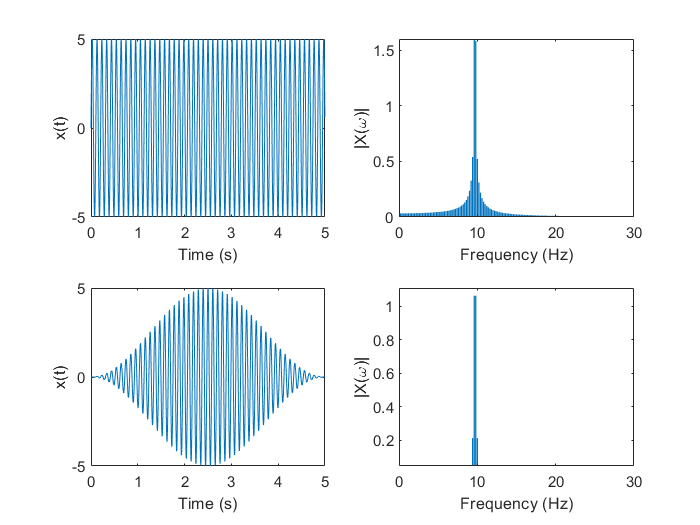

In the top row you can see how the usual leakage effect that was seen earlier, the true frequency is 9.7 Hz which is still where the peak is centred but there is significant content at other frequencies which is not really there in the signal. On the bottom row you can see a Hann window applied to the signal which enforces periodicity and greatly reduces (but doesn't remove leakage). 

MATLAB has a number of built in windowing functions, `hann`, is just one of them. Other popular choices for periodic signals include `hamming` and `blackmanharris`. We will not cover the specific properties of each window and why you might choose one or another on this course. 

**A Word of Warning: **If your signal is not periodic, i.e. it has lots of information at the beginning or end, then windowing may do more harm than good. Think carefully about the type of signals you are working with, you should always be able to say *why* you have applied a particular piece of processing.

**Task: **Clear your workspace and create a sine wave with an amplitude of 5, frequency of 9.7 Hz and no phase offset for time from 0 to 5 seconds with a sample rate of 512 Hz. Create a plot similar to the one above, the top row should have the time domain and frequency domain amplitude plots for the raw signal. Apply a Hann window to the signal and plot on the bottom row the time domain and frequency domain amplitude plots. (*Hint: remember elementwise multiplication requires *`.*`)

% Clear workspace
clear

% Code to create the wave


% FFT No Windowing

% Windowing


% FFT with window


% Plotting
figure


### 3.3 Leakage and Transient Signals

A continuous signal usually has consistent properties across the data block to which the Fourier Transform is applied. Hence reducing the significance of the start and finish (for example, by applying a Hann window) does not alter the basic information that it contains.

For a transientsignal however, the frequency content, phasing and amplitudes can change within the data block. Thus a window that focuses only on the middle of the block could fundamentally change the signal characteristic. For this reason, it is best to capture the entire transient signal in one block.

If this is not possible, special care needs to be taken when applying the FFT. For free vibration, an exponential window is sometimes used.

### 3.4 Investigating Phase Lags

So far we have only looked at sine waves with no phase lag, i.e. y = A sin ( wt ). 

**Task: **Investigate the effect of a phase lag on the leakage of a signal, create a 10 Hz sine wave with amplitue 2 with and without a phase lag of your choosing (remember the lag should be between 0 and $2\pi$). Take the FFT of each of these waves and see if they are different. Now do the same for 9.7 Hz, does the phase lag affect leakage?

### 3.5 0 Hz Offsets

A 0 Hz offset is when a signal has a nonzero mean, this is common in experimental results for a number of reasons. Remember that in the DFT the summation of frequencies starts from 0 not from 1, there is a good reason for this. The first spectral component tells you about the 0 Hz offset, it should be zero if the mean of the signal in the time domain is zero.

Here are two FFT amplitude plots, both of a 10 Hz sine wave, the top one has an offset.

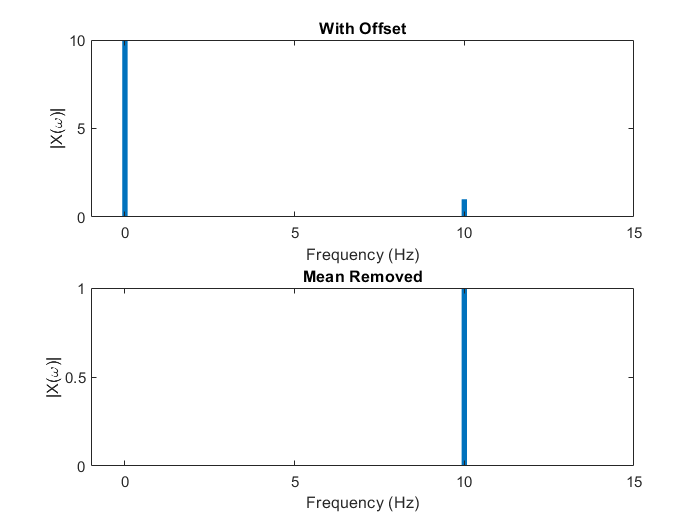

For continuous signals, we generally recommend subtracting the mean from a signal so that the 0 Hz component doesn’t show up in the FFT.

**Task: **What kind of signal would you NOT make want to subtract the 0 Hz component from? If you can't think of any ask a GTA.

## 4. Overcoming Noise

As we all know experimental tests aren't perfect and sometimes our data doesn't look as good as we would like.

### 4.1 What is Noise?

Noise is any additional components in a measured signal that mask or distort the behaviour of interest. This could be physical – e.g. trying to take acceleration readings on a turbulent airplane – or electrical – e.g. “mains hum” at 50 Hz.

Signal to Noise Ratio (SNR) defines how much stronger the signal of interest is than the noise, this is usually given in Decibels (dB).

We also talk about noise levels as a percentage of the signal level of interest, this can give an idea of the uncertainty in a reading.

We can get narrowband (a single or very few frequencies) or broadband (many frequencies) noise. It is usually easier to identify and remove sources of narrowband noise, or at least account for them and remove them.

Commonly the term noise is used to refer to broadband white noise. White noise theoretically has a flat spectrum –it excites every frequency band equally. We can model this using a Gaussian distributed random number. To make a Gaussian random sequence in MATLAB you can use `randn`. A white noise signal is shown in the figure below. A property of white noise is that its derivative is undefined at any point in time, i.e. it is always jumping from one value to another.

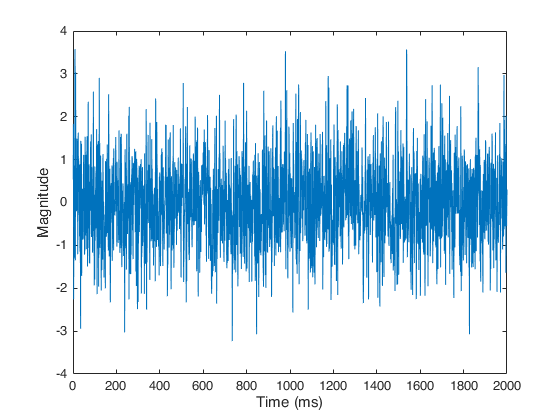

### 4.2 Investigating the Effects of Noise

We can now investigate the effect of noise on the FFTs of some signals by adding artificical noise to know signals in Matlab.

**Task: **Investigate the effect of noise.

- Clear your workspace.

- Make a sine wave with an amplitude 2 and frequency = 10Hz.

- Create a noise vector the same length as the signal.

- Create a new signal from the sine wave with the noise added to it.

- Create a figure with three subplots showing the original signal the noise and the signal corrupted by noise.

- Compute and compare the amplitude components of the FFTs for the original sine wave, the noise its self and the corrupted signal.

- What difference does the noise make in the frequency domain.

- Change the amplitude of the noise to see the effect this has.

clear

% Code to create the wave


% Create noise


% Noisy signal


% Plot noisy data
figure



% FFT of noisy and the frequency calculation


% Plot FFTs
figure

Hopefully, you can see the difference between the clean and noisy signals in the plot above. Do you think it is easier to think about noise in the time-domain or frequency-domain?

### 4.3 Perfection, Noise and the Universe

Remember that in theory the content of a perfect white noise will be a completely flat spectrum, i.e. it has the same energy in every frequency up to infinity. Clearly this will be impossible to achieve because we cannot get to infinite sampling frequency but in reality we also run into another problem. We never see a completely flat spectrum because of two things:

- Our noise is normally band-limited, it has an upper bound on its frequency content

- We use a finite set of samples from a white noise process

Because we have a finite set of samples we we never quite see the equal energy content in every frequency of the signal, normally this is not a big problem but it does explain why the frequency domain plot of the noise you have above does not look like a perfectly horizontal line.

### 4.4 Dealing with Noise

Remember that we said you could think about noise as a completely flat frequency spectrum (with random phase) or as a [Gaussian (Normal) distributed random number](https://en.wikipedia.org/wiki/Normal_distribution). In other words, at any point in time our noise $n_t$can be written as,


$$n_t \sim\mathcal{N}\left(0,\sigma^2\right)$$


Notice how the mean of the noise process is zero. We have also assumed an *additive *noise process, this means that our noise is simply added on top of the signal that we are interested in. This means we can think of our signal as a random number as well but this time the noisy signal at a time t $y_t$ will be distributed 


$$y_t \sim\mathcal{N}\left(x_t, \sigma^2\right)$$


In other words, if we do lots of experiements the mean of those experiements will be the noise free signal we are interested in $x_t$. What we then have to do is to approximate the signal we want $x_t$ as the sample mean of multiple copies of $y_t$ and our estimate will get better the more samples we have. This is a slightly more formal way of saying we do a number of experiments and then take the mean (average) of our measurements.

Or at least that's how it works in theory, however, in practice things might be a little different and we have an important choice to make. Do we average our measurements in the time domain or the frequency domain?

The code below creates 10 realisations of a sine wave each with a different realisation of the same amplitude random noise added,

clear

% Code to create the wave


% Create 10 realisations of the random noise
% One realisation per column

% Noisy signal - each column of y has different noise added


% Plot
figure


Our first option is just to take the average over these realisations of the signal (the columns of y) and that should remove the noise. Let's see what happens and also look at the frequency domain for the unaveraged and averaged.

% FFT of different y realisations and the frequency calculation

% Averaging in time domain

% Averaging in the frequency domain

% Plotting
figure

% Hint: xlim([0,20]) % Zoom in on x axis for ease of viewing

From the graphs above it doesn't really look like there is much difference between the time domain and the frequency domain.

Now let's consider a different scenario where we are collecting data from a sine wave but we aren't always able to start collecting at the beginning of a cycle, this introduces a random phase offset. The code below generats such a wave.

clear

% Code to create the wave


% Create 10 realisations of the random noise
% One realisation per column


% Noisy signal - each column of y

% Plot
figure


You can see that this random phase has shifted the waves left and right in the plot. 

**Task: **Perform averaging and create the sample plots as we did before but for the signals with phase offsets. What do you notice? What would happen as the number of samples increased?

% Frequency domain samples and frequency calculation


% Averaging in time domain

% Averaging in the frequency domain

% Plotting
figure

When it comes to dynamic testing we often cannot control accurately the phase content of the signal that we are measuring but we know the frequency content will be very similar.

Think about when might be the best time to do averaging if you are working with dynamic testing data. Ask a GTA if you are unsure.

## 5. Forming FRFs From Experiemental Data

After all that background we can finally think about how we might process some modal analysis data to get the FRFs!

We will now apply these methods to experimental data collected from a structure similar to the one you will analyse in your lab and assignment.

The test involves a steam turbine blade which is tapped at 10 locations with an instrumented hammer. You will find out more when you complete the lab in the Diamond and read the lab sheet and assignment brief.

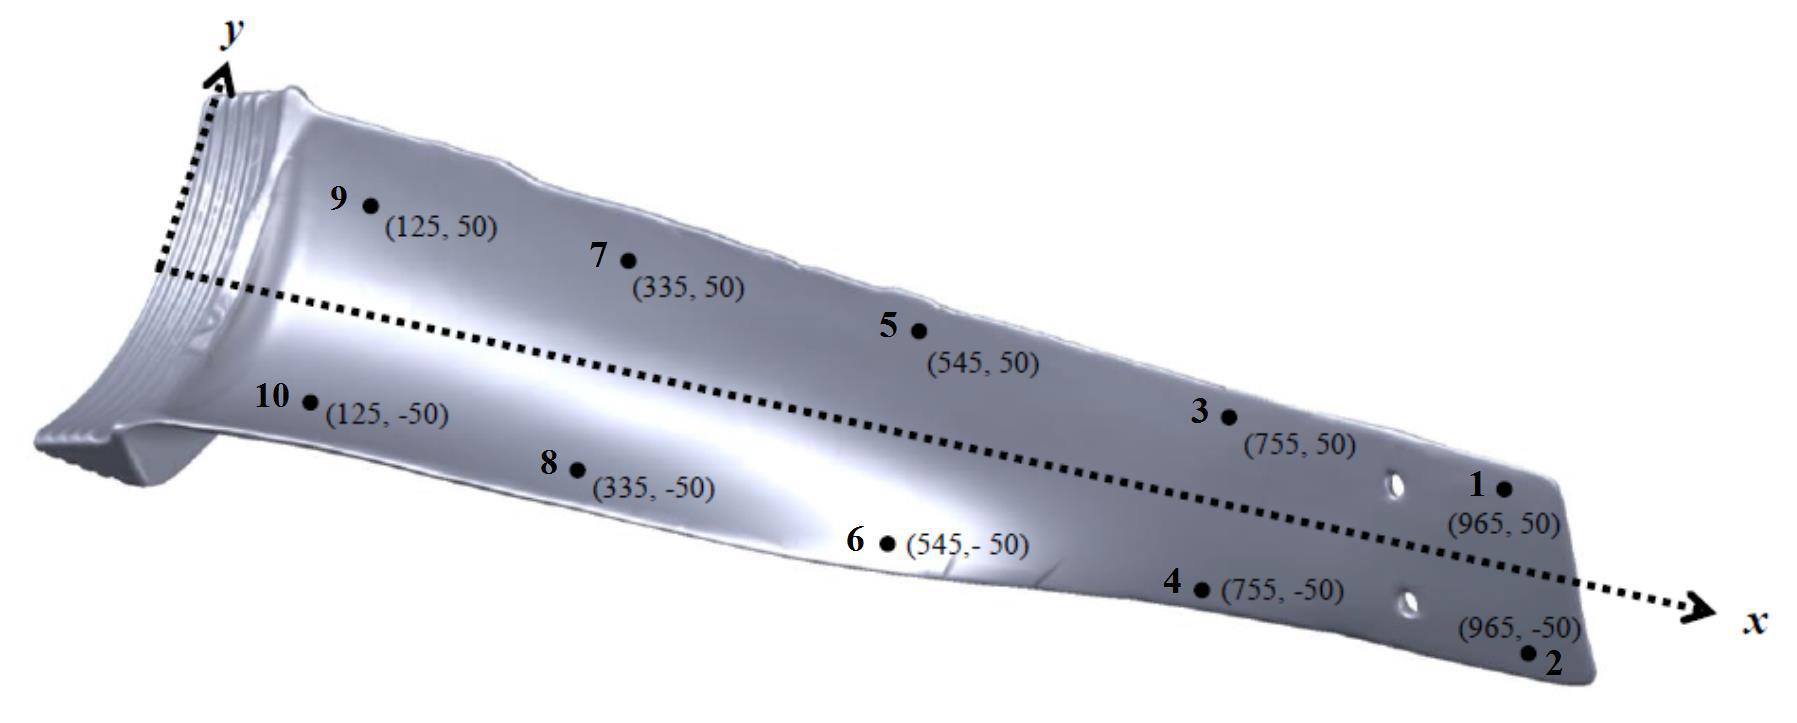

Above is shown an image of the steam turbine blade with the tap locations marked on it.

### 5.1 Loading the Test Data

We have provided an example set of data for this lab which was collected by some PhD students on a similar blade several years ago using the same test procedure you will/have.

This data will also be used to create the `blade1_data `which is needed in the assignment.

We have provided functions for loading the data collected in the lab which is in `.tdms` format into Matlab. When you have done this you should save the data in a Matlab format.

**Task: **Load the data into Matlab and save as `blade1_data.mat`

- Clear your workspace

- Download the file called “`Lab2_example_data.zip`” from Blackboard to the folder that you are working in.

- Unzip in this location and check that you have a files called “`get_tap_test_data.m`”, “`blade_E.tdms`” and a folder called “`Version_2p5_Final`”

- In MATLAB, run the loading function by typing the command, `point = get_tap_test_data; `this will save the data in a structure called `point `you can change the name of this variable if you like and should use a different name for the second dataset.

As the function runs, you will need to provide information. The list below gives the queries (left of arrow) and how you should respond (right of arrow).

- `DIALOG: Download TDMS Worker Functions and select folder -> OK`

- `MENU: File name -> Select folder Version_2p5_Final`

- `DIALOG: Select your .tdmsdata file -> OK`

- `MENU: File name -> Select blade_E.tdms`

- `DIALOG: Enter number of test points -> 10 `(Note: this will be 10 in your lab test)

- `DIALOG: Enter number of averages -> 5 `(Note: this will be the number of repeats you make in your lab test)

% Load data here
clear
% point = get_tap_test_data;

### 5.2 Saving the Data

The previous steps have collected all the test data you need into a MATLAB data structure called `point`

A data structure is an array that groups related data (e.g. all the acceleration measurements) using data containers called fields. Review the first Matlab tutorial if you are unsure about how to use structures.

If measurements were made by tapping at 10 different locations, the array will have 10 elements. Hence point(3) will locate data associated with impacts at the third tap point.

**Task: **To avoid having to go through the procedure to load the data again every time you restart, save the data structure in your current folder in a MATLAB file called `blade1_data.mat` in the box below

% Save data here
% save('blade1_data','point');

% Clear 
clear

% Add code to load the data you just saved

The structure containing the test data has three fields:

- Time

- Input (force, measured by a force transducer on the tip of the hammer)

- Output (acceleration, measured by an accelerometer attached near the tip of the blade)

To access a particular result, you need to specify the structure name, the element number and the field name that you want. For example, the response data for tests at location 3 the syntax would be: `point(3).output`

If the data involved several “averages”, the time, input and output fields will be matrices with one column per response.

### 5.3 Exploring the Data

The first step in most analysis is to explore the data and make some initial plots so you get an idea of what is going on. It is often at this stage that you can visually see if there are any obvious bad tests.

**Task: **Explore the data.

- Calculate the sampling frequency of the test. Note that the time signal for the second test at location 5 would be accessed using, `point(5).time(:,2)`

- Plot some of the inputs and outputs in the time domain. Think about what kind of signals these are and what the FFT is likely to show us. Maybe zoom in on the input signals.

- Calculate and plot the FFT amplitude of the inputs and outputs at some of the points

% Calculate sample frequency, assume it is the same for all tests.

% Input-Output Time Domain Plots
figure


% Input-Output Frequency Domain Plots


We can think about what an appropriate frequency range might be and only look at the plots in that region. What do you think a appropriate range might be? You can zoom in on the plots to take a look.

If we zoom in, we can see that if we focus on the range 0-1000Hz, the spectra are relatively flat. That means we are exciting all frequencies between 0-1000Hz equally. You might be able to argue that higher than this would be acceptable.

One possible argument is that the maximum frequency excited by the hammer strike can be approximated to 1/time with the hammer in contact. For this test this is roughly 3000Hz. However, we will only be interested in the first 5 modes so consider what frequency you need to go up to.

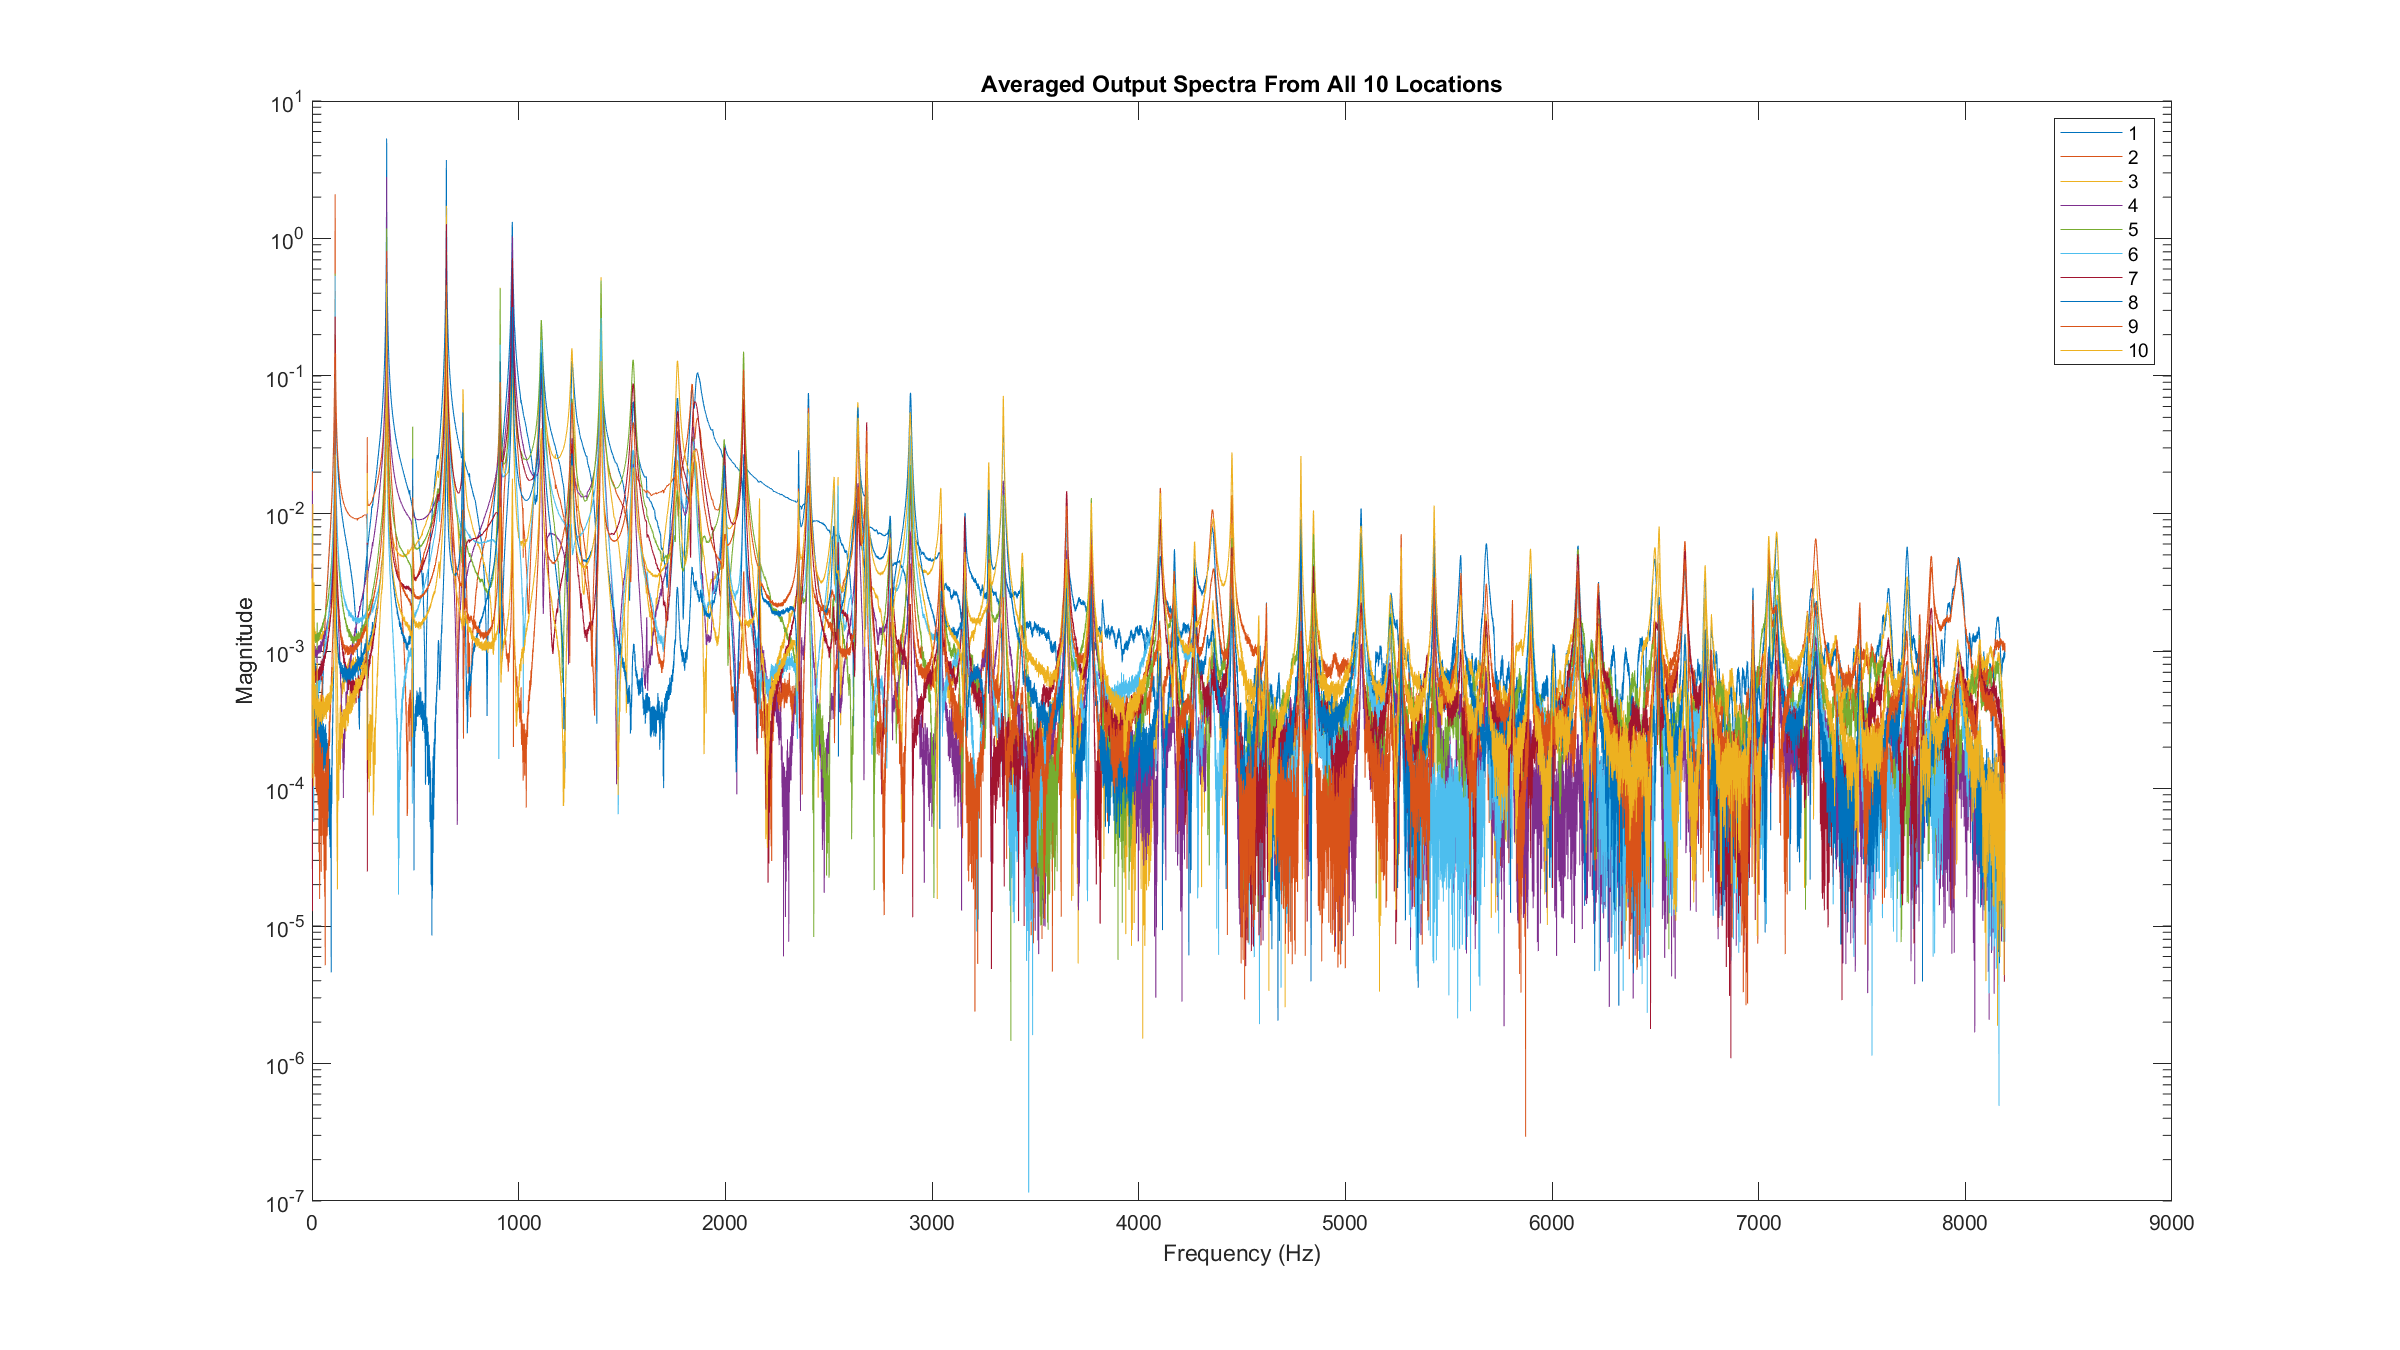

In the figure above you can see the averaged output spectra from all of the 10 locations. 

**Task: **Recreate the figure above in the code below and zoom in to 1000Hz to see more clearly the structure of the lower order modes.

% Number of measurement points

% FFTs and averaging for each point

% Frequencies

% Plotting
figure


### 5.4 FRFs

So we now have the input and output specta for each location we can think about computing the FRFs. 

For impact tests we can simply calculate the FRFs by dividing the FFT of the response (Y) with the FFT of the input (X). The following code shows the simplest way to do this, an element-wise division of the FFT of the outputs and the FFT of the inputs.

At this point think if you would want to average the spectra (Y and X) or the resulting FRFs. Maybe discuss this with another person on the course or a GTA.

For a random vibration test, or to be more rigorous generally, we can calculate the FRFs using power spectral densities (you can read more about these in Ewins’s book if you would like). These approaches are more robust to noise but we will stick with the basic calculation above for now.

**Task: **Calculate the (average) FRFs for each location using the spectra you have computed already. Make a plot of the FRFs in a range 0-1000 Hz

% Compute FRFs

% Plotting
figure

**Task: **Before you move on to the assignment here are a few things to consider.

- What features of the FRFs can you identify? How many modes are present in the 0-1000 Hz range?

- Can you identify which point the accelerometer was attached at?

- There are areas of the FRF which appear to contain noise, how would you minimise this noise if designing an experiment? *(Hint: how did we deal with noise before)*

## 6 The End

We have now reached the end of this Matlab tutorial.

It is strongly advised that you work through any slides that you didn’t get a chance to look at in the computer session at home. 

Bring any questions you have to the drop-ins which are running later in the semester or you can use the discussion board to ask questions.

In the drop-ins, you can also ask the demonstrators to provide you with some feedback on any code you have written for the assignment by that time. Remember they won't be able to do the assignment for you but will be very happy to help if you have specific queries.